# 計算グリッドの修正

## 　従来のシミュレーション条件は不適切であった．

## 　計算グリッドの間隔がセンサ位置を考慮せずに設定されており，センサをグリッド上に配置した際に，センサ間隔が不均一になるという問題を抱えていた．

## 　そこで，計算グリッドの再設定を行う．再設定を行い次第，今まで行った主要なシミュレーションを再度実行する．

load("\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\param\param_2board.mat")
load("\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_09_28_realisticScatter_variousIMCL\case1_IMCL1.8\sensor.mat")
load("\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_09_28_realisticScatter_variousIMCL\case2_IMCL1.0\mask_points.mat")

sensor.mask

ans =    -0.0200   -0.0196   -0.0192   -0.0188   -0.0184   -0.0180   -0.0176   -0.0172   -0.0168   -0.0164   -0.0160   -0.0156   -0.0152   -0.0147   -0.0143   -0.0139   -0.0135   -0.0131   -0.0127   -0.0123   -0.0119   -0.0115   -0.0111   -0.0107   -0.0103   -0.0099   -0.0095   -0.0091   -0.0087   -0.0083   -0.0079   -0.0075   -0.0071   -0.0067   -0.0063   -0.0059   -0.0055   -0.0051   -0.0046   -0.0042   -0.0038   -0.0034   -0.0030   -0.0026   -0.0022   -0.0018   -0.0014   -0.0010   -0.0006   -0.0002
    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200   

length(sensor.mask)

ans = 200

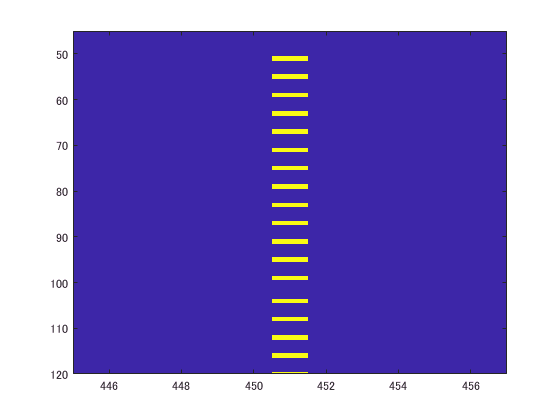

figure;imagesc(mask_points);
xlim([445 457])
ylim([45 120])

外観を見てもセンサが等間隔で並んでいるようには見えない．実際，

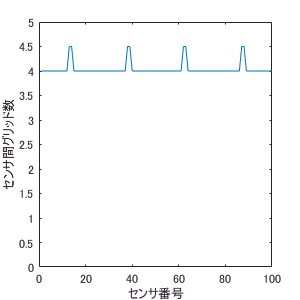

[row,~] = find(mask_points(:,200:end));
grad_sensor_position = gradient(row);
figure;plot(grad_sensor_position);ylim([0 5])
xlabel('センサ番号')
ylabel('センサ間グリッド数')
exportfig("\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_10_06_correct_kwave_conditions\non_flat",'png',[300, 300]);

センサが配置されているグリッドに対応するインデックスが格納されているセンサーベクトルに対する一次元数値勾配を要素に持つ配列を上にプロットすると，

センサが等間隔に配置されていないことが見てとれる．

次に，sensor.mask(mask_points)がどこで定義されているか確認する．

"\\Azlab-fs01\東研究室\個人work\竹内(ひ)\USCTSim-master\simulate_usct.m"で定義されていた．

トランスデューサ長さを396 mmにすれば，すべてのセンサー位置がグリッド中心と一致する．（素子数100*2）

トランスデューサ長さを400 mmに固定したければ，素子数を101素子にする必要がある．

どちらにするかは個人差があるだろうが，前者にしようと思う．101素子というのが気持ち悪い．

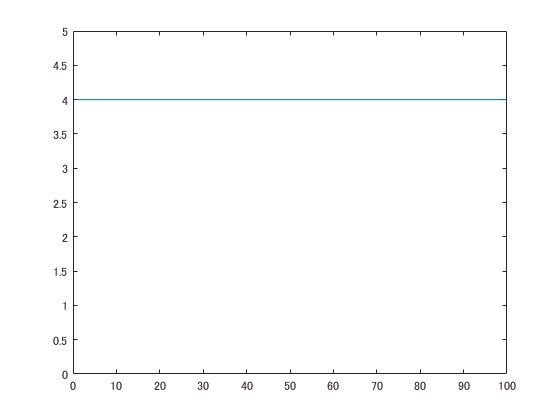

load("\\Azlab-fs01\東研究室\個人work\竹内(ひ)\experiments\2018_10_06_correct_kwave_conditions\mask_points.mat");
[row,col] = find(mask_points(:,200:end));
grad_sensor_position = gradient(row);
figure;plot(grad_sensor_position);ylim([0 5])

これで問題は解決された．

念のために，現在実行中のファイル"\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\script\2018_09_28_realisticScatter_variousIMCL\Corrected\main_script.m"で出力される

"\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_09_28_realisticScatter_variousIMCL\Correct\case4_IMCL2.0\mask_points.mat"

におけるセンサ間隔をチェックする．

パスをバックアップフォルダに指定していた．バックアップファイルは変更を反映していない．失敗だ．気づけてよかった．

load("\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_10_15_realisticScatter_variousIMCL_Correct\case3_IMCL0.8\mask_points.mat");
[row,col] = find(mask_points(:,200:end));
grad_sensor_position = gradient(row);
figure;plot(grad_sensor_position);ylim([0 5])

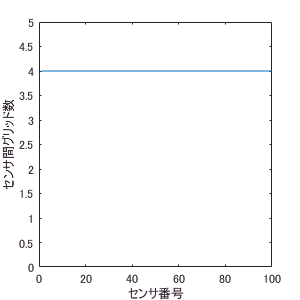

load("\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_10_15_realisticScatter_variousIMCL_Correct\case1_IMCL0.4\mask_points.mat")
[row,col] = find(mask_points(:,200:end));
grad_sensor_position = gradient(row);
figure;plot(grad_sensor_position);ylim([0 5])
xlabel('センサ番号')
ylabel('センサ間グリッド数')
exportfig("\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_10_06_correct_kwave_conditions\flat",'png',[300, 300]);